# AES learning Scientific Computing with Matlab by 

Prof. Joseph Morlier

## 0. Summary

1. Defining scalar  variables

2. Vector operations

3. Matrices operation

4. For Loop

5. More programming 

6. Optimization

BONUS : Numerical integration in 2D

7. Eigenvalues and Eigenvectors

8. 2D Laplace Equation (analytical)

9. 2D Laplace Equation using 2D FD (Jacobi)

10. 1D Boundary Value Problem (1D FD)

BONUS SVD Example

## 1.Defining scalar variables

**Commands** **:**      **+**  **-**   **/**   *** ** **^ ** **;**          Basic algebraic operations

**clear**                       Clear variables from the workspace

**close all**                   Close all figures

**%**                           Insert a comment

MATLAB can be used as a calculator and can store the inputs or the outputs into variables. If a semicolon “ ; ” is placed at the end of a statement, the value of the variable is calculated but not displayed on the screen. To clear variables from the workspace, use the command *clear*.

*Hint:*       To display the current value of a variable, double-click on its name in the command window.

*Hint:*       To avoid retyping previously used command, use up and down arrows

 clear all; 

### 2.Vector operations (a)

**Commands:**       **linspace (x0, x1, N)**         Create an array of N equally spaced values   between x0 and x1

**x0 : Δx : x1**        Create an  array of values between x0 and   x1 spaced by Δx

Create the vector [1 2 3 ]. Visualize the elements. Change the third element to 4 and display the new vector on the screen.

%ex1

## 2. Vector operation (b)

**Commands : .* ./ .^ **element by element algebraic operations

Define two vectors x = [1 -2 5 3] and y = [4 1 0 -1]. Multiply x and y element by element.

**Compute the squares of the elements of x.** 

Create the vector [1 2 3 ]. Visualize the elements. Change the third element to 4 and display the new vector on the screen.

%ex2
clear all; 
% Define x and y 

## 3. Matrices operation (a)

**commands:**

*****  Matrix multiplier operator 

**size ****: **Returns the size of a vector or matrix. 

**’ ****: **Matrix transpose operator 

 **round ****: **Returns integer value(s) of the argument 

Multiply two matrices 

 

Determine the size of the resulting matrix. 

clear all; 
% Initialize matrices

## 3.Matrices operation (b) Gaussian Elimination

**commands:**

**rank **: Returns the rank of a matrix

**rref **: Returns the reduced echelon of a matrix

**inv **: Returns the inverse of a matrix (squared)

**pinv:** Returns the inverse of a matrix (rectangular)

 [https://fr.mathworks.com/help/matlab/math/systems-of-linear-equations.html](https://fr.mathworks.com/help/matlab/math/systems-of-linear-equations.html)

Find the rank and solution (if it exists) to the following system of equations: 

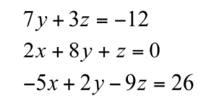

% Initialize matrix. 
clear all;  

## 3.Matrices operation (c) Regression

Let's take this example 

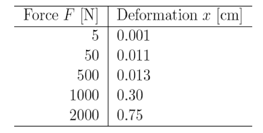

model is 

clear all;
x = [.001 .011 .13 .3 .75]*1e-2;
%The appropriate Matlab commands give (the components of x are all multiplied by 1e-2,  in order
%to change from cm to m)


## 4. For Loop 

**Command : **

**for** variable = initial value : increment : final value 

statement 

statement 

**end **

**Commands : plot Create a scatter/line plot in 1-D**

**title **Add a title to the current figure

**xlabel, ylabel legend **Add x and y labels to the current figure Add a legend to the current figure

**hold on / hold off **Plot multiple curves in the same 

**subplot** figure Make several plots in the same window

Define the following piecewise function between x = -3 and x = 5 using 1000 points and plot it.

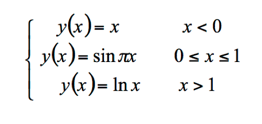

clear all; 
% Define vector x

## 5. More programming (a)

**Integrate numerically: finite difference?**

Starting from rest, a car (mass = 900 kg) accelerates under the influence of a force of 2000 Newtons until it reaches 13.89 m/s (50 km/h). What is the distance traveled? How long does it take to travel this distance?

This equation determines the velocity of the car as a function of time. To obtain the position of the car, we use the following kinematic relation:

Although this problem can be solved analytically, in this exercise we would like to come up with a numerical solution using MATLAB. We first need to discretize the equations, i.e. evaluate the position and velocity at equally spaced discrete points in time, since MATLAB doesn’t know how to interpret continuous functions. The solution for v(t ) and x(t ) will then be represented by vectors containing the values of the velocity and the position of the car respectively at these discrete points in time separated by delta_t .

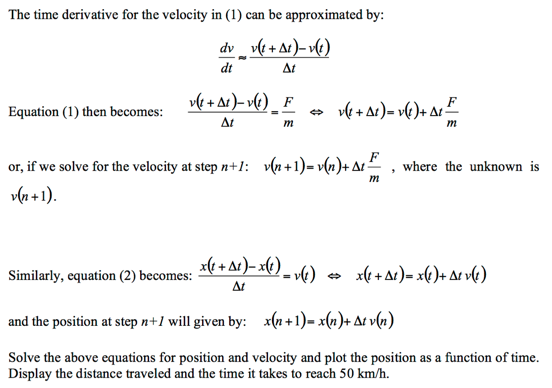

clear all; 
% Force applied to the car in Newtons

## 5. More programming (b)

**Commands :** gradient Computes the numerical derivative of a function

Find the derivative of the following function: y = xexp(-x) for x ranging between 0 and 10, with an increment

of 0.5. Plot both the analytical and the numerical derivatives in the same figure.

clear all;  

## 6. Optimization (a)

**Command : fminsearch **find a local minimum of a function a) For functions of a single variable: find the minimum of the function *f *(*x*)=1- *xe*-2*x *, first analytically 

and then numerically using the **fminsearch **command. 

*Hint: *Unlike most MATLAB operations, you don’t need to define a vector *x *before using **fminsearch**. Simply type in the function as shown below. **fminsearch **looks for the local minimum which is *closest *to the initial guess you specify as the third parameter. The syntax is:

clear all; 

## 6.Optimization (b)

For functions of several variables: find the minimum of the function f (x, y)= cos(xy)sin(x) over the domain using the fminsearch command.

Follow these steps:

- plot the function over the given domain to approximately locate the minimum. - use these approximate values of the coordinates as your initial guess

Hint: The syntax for functions of several variables is slightly different. Define X = [x y]. Then in MATLAB, x and y will be represented by the two components: X (1)= x and X (2)= y , and the command becomes:

clear all; 

## 7. Numerical integration in 2D (a)

**trapz **Computes the integral of a function over a given domain using the trapezoidal method

Compute the integral of the function f (x) = x^2 + x +1 for 0< x <1 using the trapezoidal method. Compare the result to the exact analytical solution (Analytical result : I = 11/6 = 1.8333)

**quad **Computes the integral of a function over a given domain using Gaussian quadrature (Numerically evaluate integral, adaptive Simpson quadrature)

clear all; 
x = linspace(0,1,100);
y = x.^2+x+1;
I = trapz(x,y)
yg=inline('x.^2+x+1');
Ig=quad(yg,0,1)

## 7. Numerical integration in 2D (a)

If you know explicitly the integrand use Gaussian quadrature (see course, why using polynomes)

Q = QUAD(FUN,A,B) tries to approximate the integral of scalar-valued function FUN from A to B to within an erro of 1.e-6 using recursive adaptive Simpson quadrature.

Suppose we wish to integrate (double) 

As before, we can use either an inline function, an anonymous function handle, or an M-file:

• Using an inline function. When defining a function of more than one variable, we can list the order in which they should appear at the end

clear all; 
     f1=inline('x.^2.*y','x','y');
% f2=@(x,y)x.^2.*y;
     Q=dblquad(f1,0,3,1,2)

I = 1.8334

Ig = 1.8333

Q = 13.5000